Demo code for Figure Supp 4 of Idesis (2022) - Edge centric analysis of stroke patients. An alternative approach for biomarkers of lesion recovery

Edge-centric code adapted from Faskowitz, J. et al (2020) and Zamani Esfahalani (2020)

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything
nodes = 200; % Amount of nodes from the dataset

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load regional time series

load data/ts.mat %Demo data (Taken from https://www.brainnetworkslab.com/coderesources)

Create fake data of 5 stroke patients

amount_of_patients= 5; %Number for demo
for subj = 1:amount_of_patients
    ts_patients(:,:,subj)= ts.*(randn(1200,200)*4); %original ts plus a bigger factor random amount to make every subject different
end

High amplitude - Patients

for subj = 1:size(ts_patients,3)
    ts = ts_patients(:,:,subj);
    ts = zscore(ts); % z-score time series
    [ntime,nnodes] = size(ts); % get dimensions
    nedges = nnodes*(nnodes - 1)/2; % calculate number of edges
    [u,v] = find(triu(ones(nnodes),1)); % indices of unique edges (upper triangle)
    idx = (v - 1)*nnodes + u;
    fc = corr(ts); %% calculate static fc
    ets = ts(:,u).*ts(:,v); %% generate edge time series
    fc_upper_triangle = fc(idx);
    rms = sum(ets.^2,2).^0.5; % calculate co-fluctuation amplitude at each frame
    frackeep = 0.1; % fraction of high- and low-amplitude frames to retain
    nkeep = round(ntime*frackeep);
    [~,idxsort] = sort(rms,'descend'); % sort co-fluctuation amplitude
    
    boundaries = [0:length(ts)/10:length(ts)];
    % estimate fc using just high-amplitude frames
    fctop_10 = corr(ts(idxsort(boundaries(1)+1:boundaries(2)),:)); fctop_10(isnan(fctop_10)) = 0;
    fctop_20 = corr(ts(idxsort(boundaries(2)+1:boundaries(3)),:)); fctop_20(isnan(fctop_20)) = 0;
    fctop_30 = corr(ts(idxsort(boundaries(3)+1:boundaries(4)),:)); fctop_30(isnan(fctop_30)) = 0;
    fctop_40 = corr(ts(idxsort(boundaries(4)+1:boundaries(5)),:)); fctop_40(isnan(fctop_40)) = 0;
    fctop_50 = corr(ts(idxsort(boundaries(5)+1:boundaries(6)),:)); fctop_50(isnan(fctop_50)) = 0;
    fctop_60 = corr(ts(idxsort(boundaries(6)+1:boundaries(7)),:)); fctop_60(isnan(fctop_60)) = 0;
    fctop_70 = corr(ts(idxsort(boundaries(7)+1:boundaries(8)),:)); fctop_70(isnan(fctop_70)) = 0;
    fctop_80 = corr(ts(idxsort(boundaries(8)+1:boundaries(9)),:)); fctop_80(isnan(fctop_80)) = 0;
    fctop_90 = corr(ts(idxsort(boundaries(9)+1:boundaries(10)),:)); fctop_90(isnan(fctop_90)) = 0;
    fctop_100 = corr(ts(idxsort(boundaries(10)+1:boundaries(11)-4),:)); fctop_100(isnan(fctop_100)) = 0;

    
    corr_top_10(subj)=corr(fctop_10(idx),fc(idx));
    corr_top_20(subj)=corr(fctop_20(idx),fc(idx));
    corr_top_30(subj)=corr(fctop_30(idx),fc(idx));
    corr_top_40(subj)=corr(fctop_40(idx),fc(idx));
    corr_top_50(subj)=corr(fctop_50(idx),fc(idx));
    corr_top_60(subj)=corr(fctop_60(idx),fc(idx));
    corr_top_70(subj)=corr(fctop_70(idx),fc(idx));
    corr_top_80(subj)=corr(fctop_80(idx),fc(idx));
    corr_top_90(subj)=corr(fctop_90(idx),fc(idx));
    corr_top_100(subj)=corr(fctop_100(idx),fc(idx));
end


Visualization

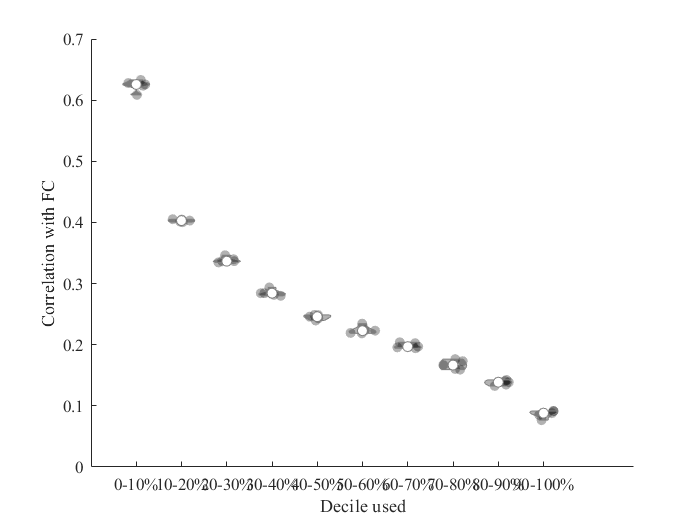

temp_combined = [corr_top_10', corr_top_20', corr_top_30', corr_top_40', corr_top_50',...
                 corr_top_60', corr_top_70',corr_top_80', corr_top_90',  corr_top_100'];
             
group = [zeros(1,length(corr_top_10)),...
        (ones(1,length(corr_top_10))*1),...
        (ones(1,length(corr_top_10))*2),...
        (ones(1,length(corr_top_10))*3),...
        (ones(1,length(corr_top_10))*4),...
        (ones(1,length(corr_top_10))*5),...
        (ones(1,length(corr_top_10))*6),...
        (ones(1,length(corr_top_10))*7),...
        (ones(1,length(corr_top_10))*8),...
        (ones(1,length(corr_top_10))*9),...
        (ones(1,length(corr_top_10))*10)];

figure()
vs = violinplot(temp_combined, group);

for z = 1:10
    vs(z).ViolinColor = 'black';
end
xticklabels({'0-10%','10-20%','20-30%','30-40%','40-50%','50-60%','60-70%','70-80%','80-90%','90-100%'})
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',10)
ylabel('Correlation with FC')
xlabel('Decile used')

Calculate Global metrics

Cluster Coefficient

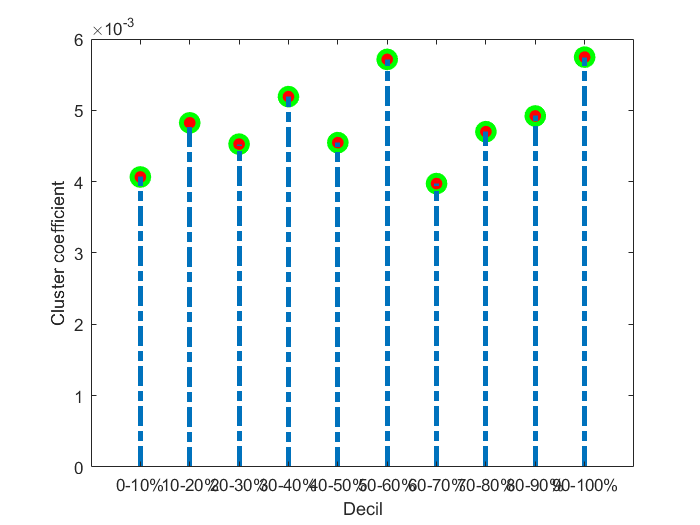

C_10=mean(clustering_coef_bu(fctop_10));
C_20=mean(clustering_coef_bu(fctop_20));
C_30=mean(clustering_coef_bu(fctop_30));
C_40=mean(clustering_coef_bu(fctop_40));
C_50=mean(clustering_coef_bu(fctop_50));
C_60=mean(clustering_coef_bu(fctop_60));
C_70=mean(clustering_coef_bu(fctop_70));
C_80=mean(clustering_coef_bu(fctop_80));
C_90=mean(clustering_coef_bu(fctop_90));
C_100=mean(clustering_coef_bu(fctop_100));

figure()
temp = [C_10 C_20 C_30 C_40 C_50 C_60 C_70 C_80 C_90 C_100];
stem(temp,'LineStyle','-.',...
     'MarkerFaceColor','red',...
     'MarkerEdgeColor','green',...
     'MarkerSize',10,...
     'LineWidth',3)
xlabel('Decil')
ylabel('Cluster coefficient')
xlim([0 11])
xticklabels({'','0-10%','10-20%','20-30%','30-40%','40-50%','50-60%','60-70%','70-80%','80-90%','90-100%'})

Global efficiency

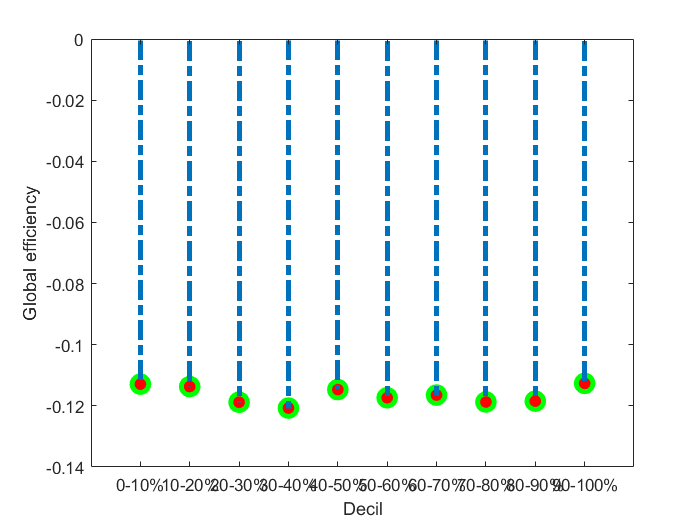


G_10=nanmean(efficiency_wei(fctop_10));
G_20=nanmean(efficiency_wei(fctop_20));
G_30=nanmean(efficiency_wei(fctop_30));
G_40=nanmean(efficiency_wei(fctop_40));
G_50=nanmean(efficiency_wei(fctop_50));
G_60=nanmean(efficiency_wei(fctop_60));
G_70=nanmean(efficiency_wei(fctop_70));
G_80=nanmean(efficiency_wei(fctop_80));
G_90=nanmean(efficiency_wei(fctop_90));
G_100=nanmean(efficiency_wei(fctop_100));

figure()
temp = [G_10 G_20 G_30 G_40 G_50 G_60 G_70 G_80 G_90 G_100];
stem(temp,'LineStyle','-.',...
     'MarkerFaceColor','red',...
     'MarkerEdgeColor','green',...
     'MarkerSize',10,...
     'LineWidth',3)
xlabel('Decil')
ylabel('Global efficiency')
xlim([0 11])
xticklabels({'','0-10%','10-20%','20-30%','30-40%','40-50%','50-60%','60-70%','70-80%','80-90%','90-100%'})

Distance

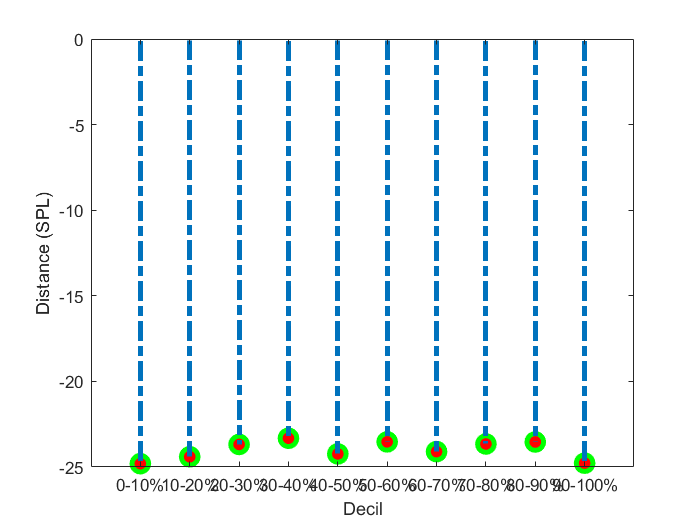

D_10=mean(nanmean(distance_wei(fctop_10)));
D_20=mean(nanmean(distance_wei(fctop_20)));
D_30=mean(nanmean(distance_wei(fctop_30)));
D_40=mean(nanmean(distance_wei(fctop_40)));
D_50=mean(nanmean(distance_wei(fctop_50)));
D_60=mean(nanmean(distance_wei(fctop_60)));
D_70=mean(nanmean(distance_wei(fctop_70)));
D_80=mean(nanmean(distance_wei(fctop_80)));
D_90=mean(nanmean(distance_wei(fctop_90)));
D_100=mean(nanmean(distance_wei(fctop_100)));

figure()
temp = [D_10 D_20 D_30 D_40 D_50 D_60 D_70 D_80 D_90 D_100];
stem(temp,'LineStyle','-.',...
     'MarkerFaceColor','red',...
     'MarkerEdgeColor','green',...
     'MarkerSize',10,...
     'LineWidth',3)
xlabel('Decil')
ylabel('Distance (SPL)')
xlim([0 11])
xticklabels({'','0-10%','10-20%','20-30%','30-40%','40-50%','50-60%','60-70%','70-80%','80-90%','90-100%'})

Assortativity

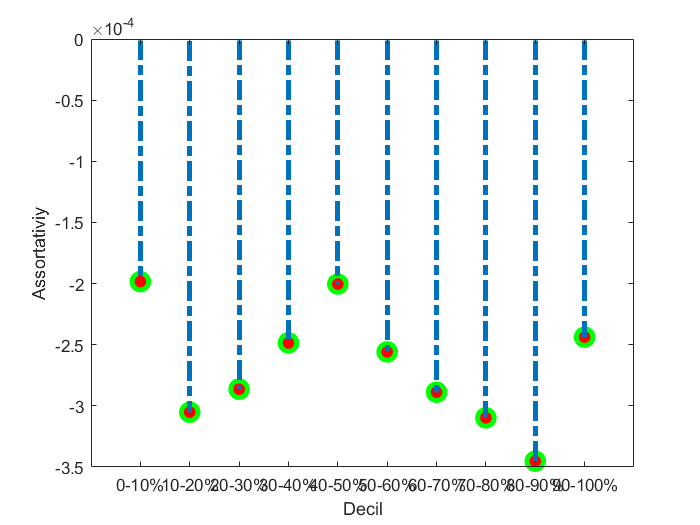

[A B]= local_assortativity_wu_sign(fctop_10); D_10_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_20); D_20_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_30); D_30_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_40); D_40_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_50); D_50_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_60); D_60_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_70); D_70_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_80); D_80_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_90); D_90_neg=mean(B);

[A B]= local_assortativity_wu_sign(fctop_100); D_100_neg=mean(B);

figure()
temp = [D_10_neg D_20_neg D_30_neg D_40_neg D_50_neg D_60_neg D_70_neg D_80_neg D_90_neg D_100_neg];
stem(temp,'LineStyle','-.',...
     'MarkerFaceColor','red',...
     'MarkerEdgeColor','green',...
     'MarkerSize',10,...
     'LineWidth',3)
xlabel('Decil')
ylabel('Assortativiy')
xlim([0 11])
xticklabels({'','0-10%','10-20%','20-30%','30-40%','40-50%','50-60%','60-70%','70-80%','80-90%','90-100%'})